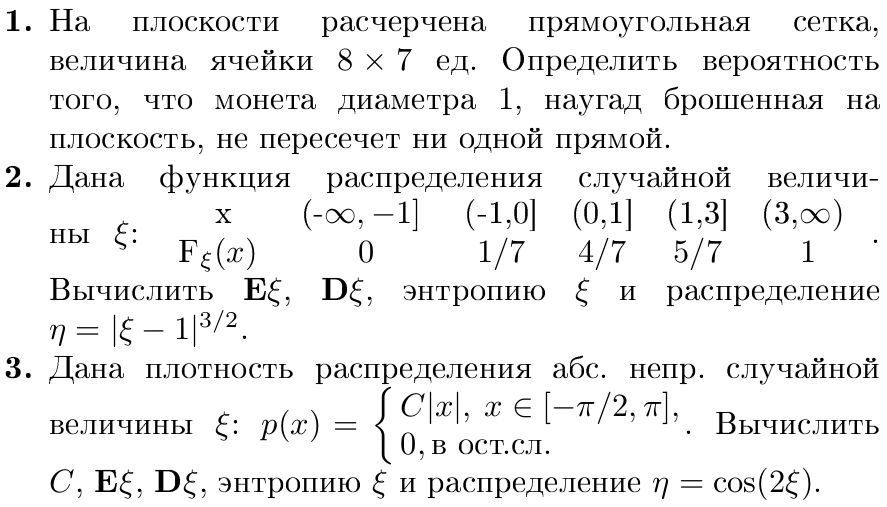

1)

p = (7*6)/(8*7)

p = 0.7500

2)

syms x
F = piecewise(x<=-1,0,x<=0,sym(1)/7,x<=3,sym(5)/7,x>3,1)

$$F = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq -1\\ \frac{1}{7} & \text{ if }x\leq 0\\ \frac{5}{7} & \text{ if }x\leq 3\\ 1 & \text{ if }3<x \end{array}\right.$$

f=[-1,0,1,3;sym(1)/7,sym(3)/7,sym(1)/7,sym(2)/7]'

$$f = \left(\begin{array}{cc} -1 & \frac{1}{7}\\ 0 & \frac{3}{7}\\ 1 & \frac{1}{7}\\ 3 & \frac{2}{7} \end{array}\right)$$

%f =[2,3,5;0.1,0.6,0.3]'
M = sum(prod(f,2))

$$M = \frac{6}{7}$$

f2= cat(2,f(:,1).^2,f(:,2));
M2 = sum(prod(f2,2));
D = M2 - M^2%Дисперсия

$$D = \frac{104}{49}$$


Entropy = sum(prod(cat(2,f(:,2),log2(f(:,2))),2))

$$Entropy = \frac{2\,\log\left(\frac{2}{7}\right)}{7\,\log\left(2\right)}-\frac{2\,\log\left(7\right)}{7\,\log\left(2\right)}+\frac{3\,\log\left(\frac{3}{7}\right)}{7\,\log\left(2\right)}$$

Entropy = simplify(Entropy)

$$Entropy = \frac{\log\left(\frac{108}{823543}\right)}{7\,\log\left(2\right)}$$

f

$$f = \left(\begin{array}{cc} -1 & \frac{1}{7}\\ 0 & \frac{3}{7}\\ 1 & \frac{1}{7}\\ 3 & \frac{2}{7} \end{array}\right)$$

N =  cat(2,abs(f(:,1)-1).^(3/2),f(:,2));
N(1,2)=N(1,2)+N(4,2);
N=N(1:end-1,:)

$$N = \left(\begin{array}{cc} 2\,\sqrt{2} & \frac{3}{7}\\ 1 & \frac{3}{7}\\ 0 & \frac{1}{7} \end{array}\right)$$

N = N(end:-1:1,:)

$$N = \left(\begin{array}{cc} 0 & \frac{1}{7}\\ 1 & \frac{3}{7}\\ 2\,\sqrt{2} & \frac{3}{7} \end{array}\right)$$

size(N,1)

ans = 3

PN = []


PN =

     []



for i=(1:size(N,1))
    tmp = cat(2,N(i),sum(N(1:i,2)));
    PN = cat(1,PN,tmp);
end
PN

$$PN = \left(\begin{array}{cc} 0 & \frac{1}{7}\\ 1 & \frac{4}{7}\\ 2\,\sqrt{2} & 1 \end{array}\right)$$

%Ent = cat(f(:,1,log2(f(:,2))))

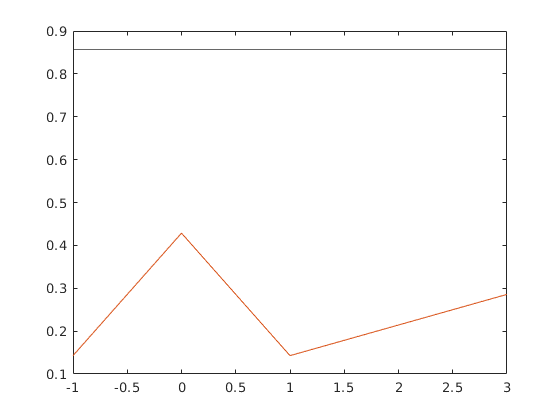

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 0.8571
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


%plot F
f = double(f);
xi = (-1:.5:4)';
yi = interp1q(f(:,1),f(:,2),xi);
plot(f(:,1),f(:,2),xi,yi)
%hold on
yline(double(M))

F

$$F = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq -1\\ \frac{1}{7} & \text{ if }x\leq 0\\ \frac{5}{7} & \text{ if }x\leq 3\\ 1 & \text{ if }3<x \end{array}\right.$$

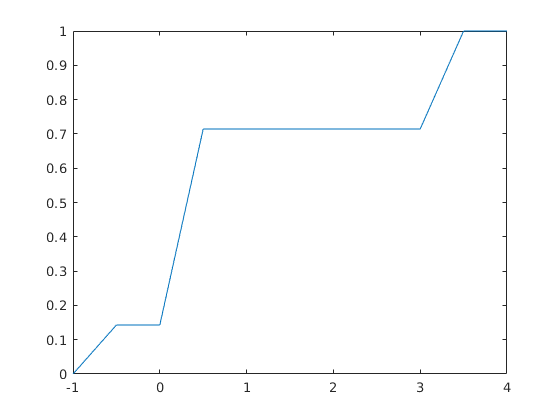


plot(xi,subs(F,x,xi))
hold off

%plot NP

PN

$$PN = \left(\begin{array}{cc} 0 & \frac{1}{7}\\ 1 & \frac{4}{7}\\ 2\,\sqrt{2} & 1 \end{array}\right)$$

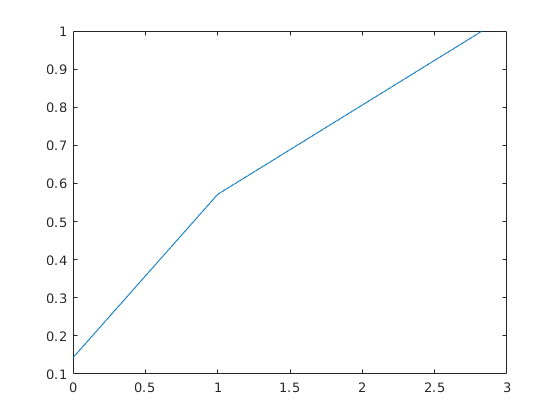

plot(PN(:,1),PN(:,2))

3)

syms x
syms C
c = 1

c = 1

p = piecewise(x<-pi/2,0,-pi/2<=x<=pi,C*abs(x),x>pi,0)

$$p = \left\{ \begin{array}{cl} 0 & \text{ if }x<-\frac{\pi }{2}\\ C\,\left|x\right| & \text{ if }x\in \left[-\frac{\pi }{2},\pi \right]\\ 0 & \text{ if }\pi <x \end{array}\right.$$

xi = -2*pi:pi/256:2*pi

xi =    -6.2832   -6.2709   -6.2586   -6.2464   -6.2341   -6.2218   -6.2096   -6.1973   -6.1850   -6.1727   -6.1605   -6.1482   -6.1359   -6.1237   -6.1114   -6.0991   -6.0868   -6.0746   -6.0623   -6.0500   -6.0377   -6.0255   -6.0132   -6.0009   -5.9887   -5.9764   -5.9641   -5.9518   -5.9396   -5.9273   -5.9150   -5.9028   -5.8905   -5.8782   -5.8659   -5.8537   -5.8414   -5.8291   -5.8169   -5.8046   -5.7923   -5.7800   -5.7678   -5.7555   -5.7432   -5.7310   -5.7187   -5.7064   -5.6941   -5.6819


C = solve(int(p,x,-pi,2*pi)==1)

$$C = \frac{8}{5\,\pi^{2}}$$

v = symvar(p,2);
p = subs(p,v(1),C)

$$p = \left\{ \begin{array}{cl} 0 & \text{ if }x<-\frac{\pi }{2}\\ \frac{8\,\left|x\right|}{5\,\pi^{2}} & \text{ if }x\in \left[-\frac{\pi }{2},\pi \right]\\ 0 & \text{ if }\pi <x \end{array}\right.$$


plot(xi,subs(p,x,xi))
hold on
syms t
P = int(p,x,-2*pi,t)

$$P = \left\{ \begin{array}{cl} 1 & \text{ if }\pi \leq t\\ 0 & \text{ if }t\leq -\frac{\pi }{2}\\ \frac{4\,t^{2}\,\mathrm{sign}\left(t\right)}{5\,\pi^{2}}+\frac{1}{5} & \text{ if }t\in \left[0,\pi \right]\\ \frac{1}{5}-\frac{4\,t^{2}}{5\,\pi^{2}} & \text{ if }t\in \left(-\frac{\pi }{2},0\right) \end{array}\right.$$

M = int(p,x,-inf,inf)

$$M = 1$$

xline(double(M))

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 1
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


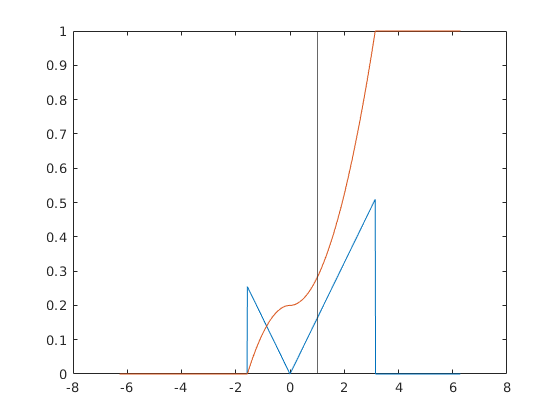


plot(xi,double(subs(P,t,xi)))
hold off

D = int((x-M).^2*p,x,-inf,inf)

$$D = \frac{17\,\pi^{2}}{40}-\frac{14\,\pi }{15}+1$$


double(D)

ans = 2.2624

p*log2(p)

$$ans = \left\{ \begin{array}{cl} \frac{8\,\log\left(\frac{8\,\left|x\right|}{5\,\pi^{2}}\right)\,\left|x\right|}{5\,\pi^{2}\,\log\left(2\right)} & \text{ if }x\in \left[-\frac{\pi }{2},\pi \right] \end{array}\right.$$

Entropy = int(p*log2(p),x,-pi/2,pi)

$$Entropy = -\frac{\log\left(\frac{5\,\pi \,2^{1/5}}{8}\right)+\frac{1}{2}}{\log\left(2\right)}$$


syms t

N = subs(p,x,cos(2*x))

$$N = \left\{ \begin{array}{cl} 0 & \text{ if }\cos\left(2\,x\right)<-\frac{\pi }{2}\\ \frac{8\,\left|\cos\left(2\,x\right)\right|}{5\,\pi^{2}} & \text{ if }\cos\left(2\,x\right)\in \left[-\frac{\pi }{2},\pi \right]\\ 0 & \text{ if }\pi <\cos\left(2\,x\right) \end{array}\right.$$


PN = int(N,x,0,t)

$$PN = \left\{ \begin{array}{cl} 0 & \text{ if }t=0\\ \int_{0}^{t}\frac{8\,\left|\cos\left(2\,x\right)\right|}{5\,\pi^{2}}\mathrm{d}x & \text{ if }t\neq 0 \end{array}\right.$$

PN = simplify(PN)

$$PN = \left\{ \begin{array}{cl} 0 & \text{ if }t=0\\ \frac{8\,\int_{0}^{t}\left|\cos\left(2\,x\right)\right|\mathrm{d}x}{5\,\pi^{2}} & \text{ if }t\neq 0 \end{array}\right.$$